# **非線形常微分方程式で表された**

# **3バス発電機の内部状態についての時間応答**

## ＜初期設定＞

・応答時間: tspan

・発電機内部状態の初期値: initial_generator_state

・発電機内部状態の定常値: steady_generator_state

clear

tspan = [0 100];

initial_generator_state = [5;2.1;1.1;3;2.1;1;0;0;0];

steady_generator_state = [1;2;1.1;3;2;1.5;0;0;0];

## ＜表示内容＞

・上記初期設定における時間応答のグラフ

 [ δ , E , Δω ] に関して

・初期値と定常値の差: initial_delta 

・最終値と定常値の差: final_delta

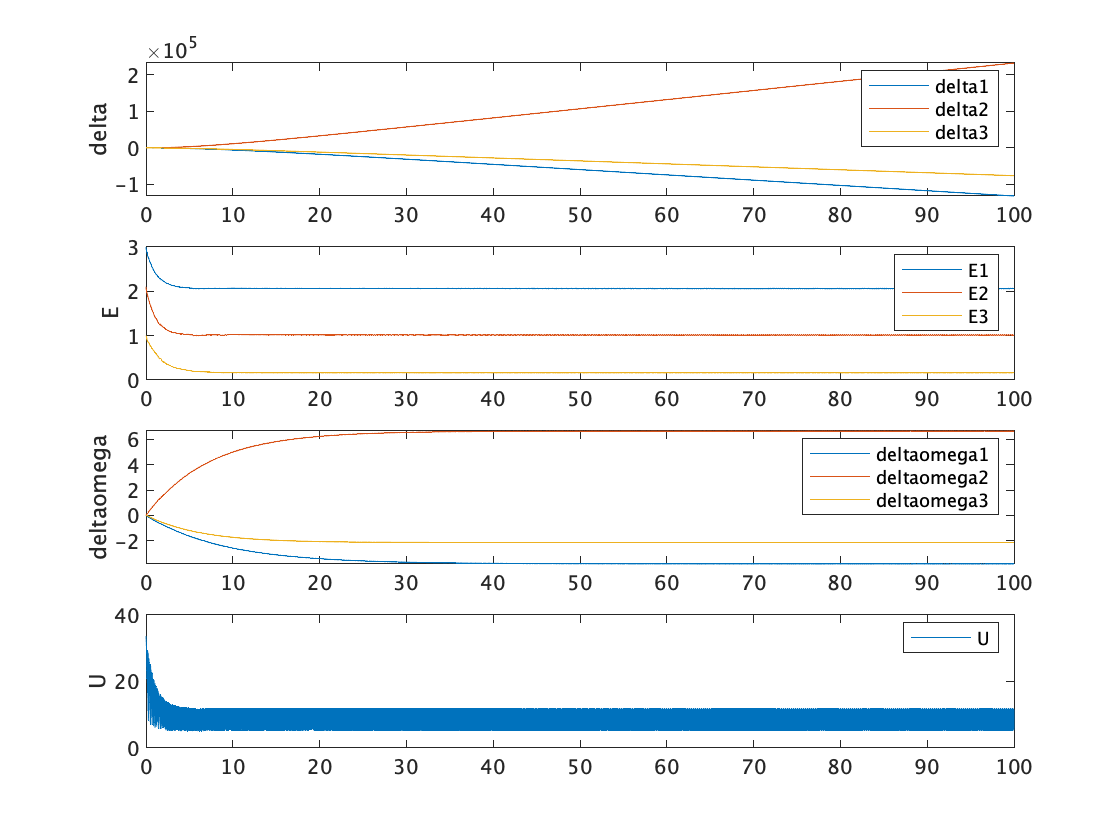

generator_state_ode_solver_for_livescript

initial_error = initial_generator_state - steady_generator_state;
initial_error = reshape(initial_error, 3, 3)

initial_error =     4.0000         0         0
    0.1000    0.1000         0
         0   -0.5000         0



final_error = transpose([delta(end,:) initial_E(end,:) deltaomega(end,:)]) - steady_generator_state;

クリアされた変数 initial_E への参照です。

final_error = reshape(final_error,3,3)
initial_error = initial_generator_state - steady_generator_state;

定常値からの微小偏差による影響

for cnt = -16:-0.5:-16.5

tspan = [0 100];

initial_delta = [1;0.1;3];
initial_E = [1;0.2;3];
initial_deltaomega = [0;0;0];
initial_generator_state = [initial_delta; initial_E; initial_deltaomega];

error = 10.^cnt;
steady_generator_state = initial_generator_state + [1;-1;1;-1;1;1;0;0;0]*error;

generator_state_ode_solver_for_livescript
sgtitle(["誤差：1e",cnt])
initial_error = initial_generator_state - steady_generator_state;
initial_error = reshape(initial_error, 3, 3)
final_error = transpose([delta(end,:) E(end,:) deltaomega(end,:)]) - steady_generator_state;
final_error = reshape(final_error,3,3)
if final_error == zeros(3)
    break
end
end

上記のbinary_search version

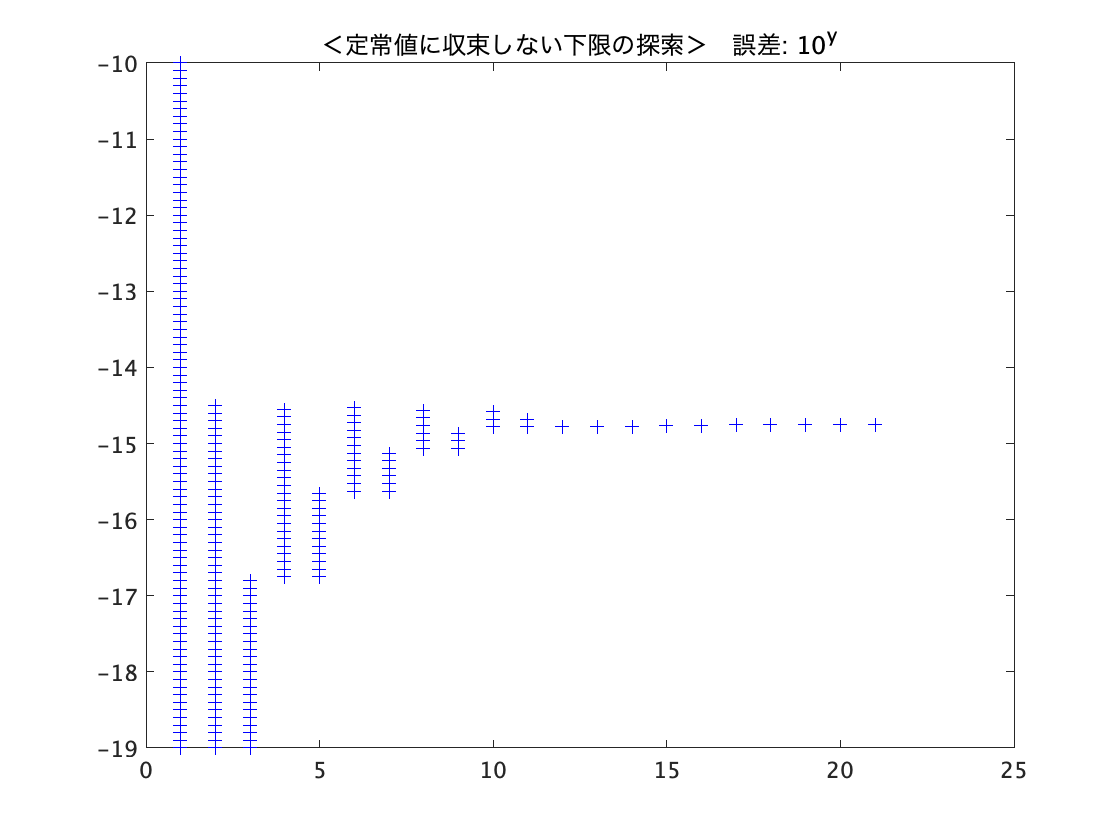

ans = 4

clear
left = -10;
right = -1;

tspan = [0 100];

initial_delta = [61;34;52];
initial_E = [35;21;18];
initial_deltaomega = [0;0;0];
initial_generator_state = [initial_delta; initial_E; initial_deltaomega];

get_final_error_wrap = @(error) get_final_error(error,tspan,initial_generator_state);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
f1 = figure;
f2 = figure;

while max(abs(error_right(:))) > 1 | all(error_right(:)) == 0
    
    if all(error_left(:)) == 0 & any(error_right(:)) ~= 0
        
        %1
        
        right = (right + left) /2;
        
        if (right - left) < 0.001
            4
            break
        end
        
    elseif  all(error_right(:)) == 0
        
        %2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:)) ~= 0
        
        %3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - right);
      
    end
    %[left, right]
    figure(f1);
    plot(t,left:0.1:right,'b+')
    title('＜定常値に収束しない下限の探索＞　誤差: 10^y')
    hold on
    
    if max(abs(error_right(:))) > 0
        figure(f2);
        plot(t,max(abs(error_right(:))),'r*')
        title('定常値との最大誤差の絶対値')
        hold on
    end
    
    t = t + 1;
    
    error_left = get_final_error_wrap(left);
    error_right = get_final_error_wrap(right);

end

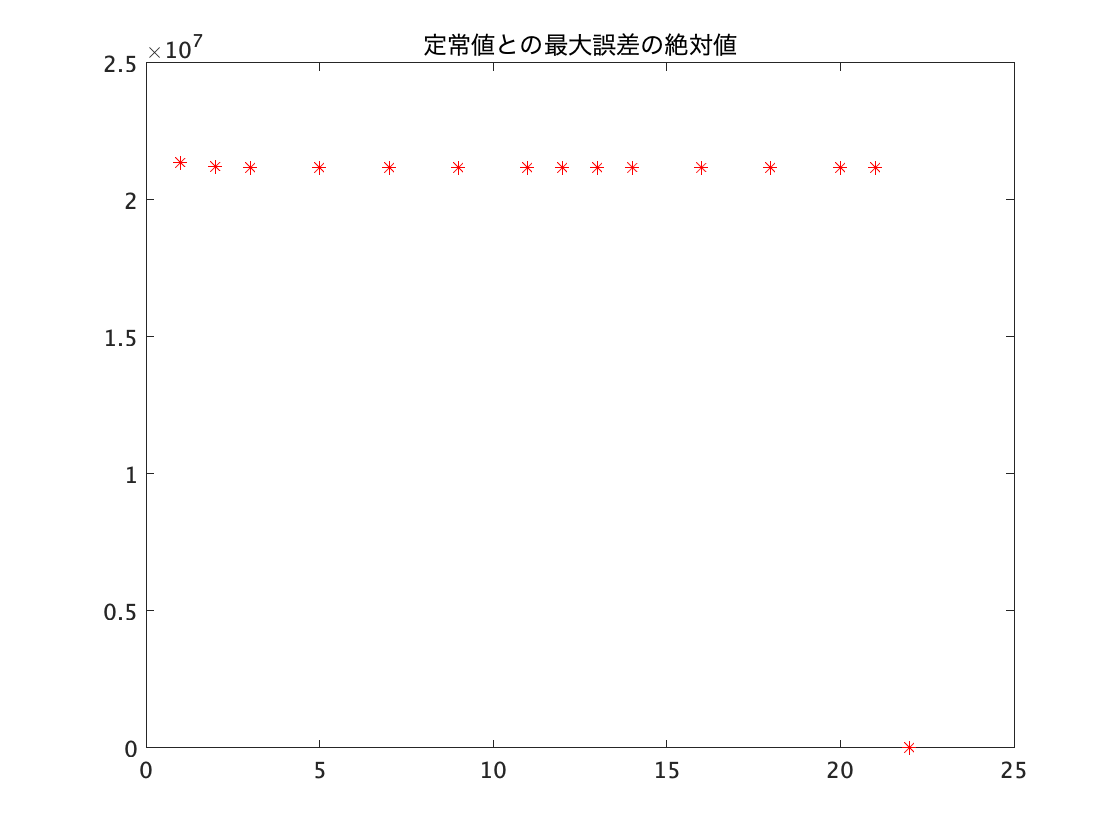

figure(f2);
plot(t,max(abs(error_left(:))),'r*')
hold off

right

right = -14.7499

left

left = -14.7505

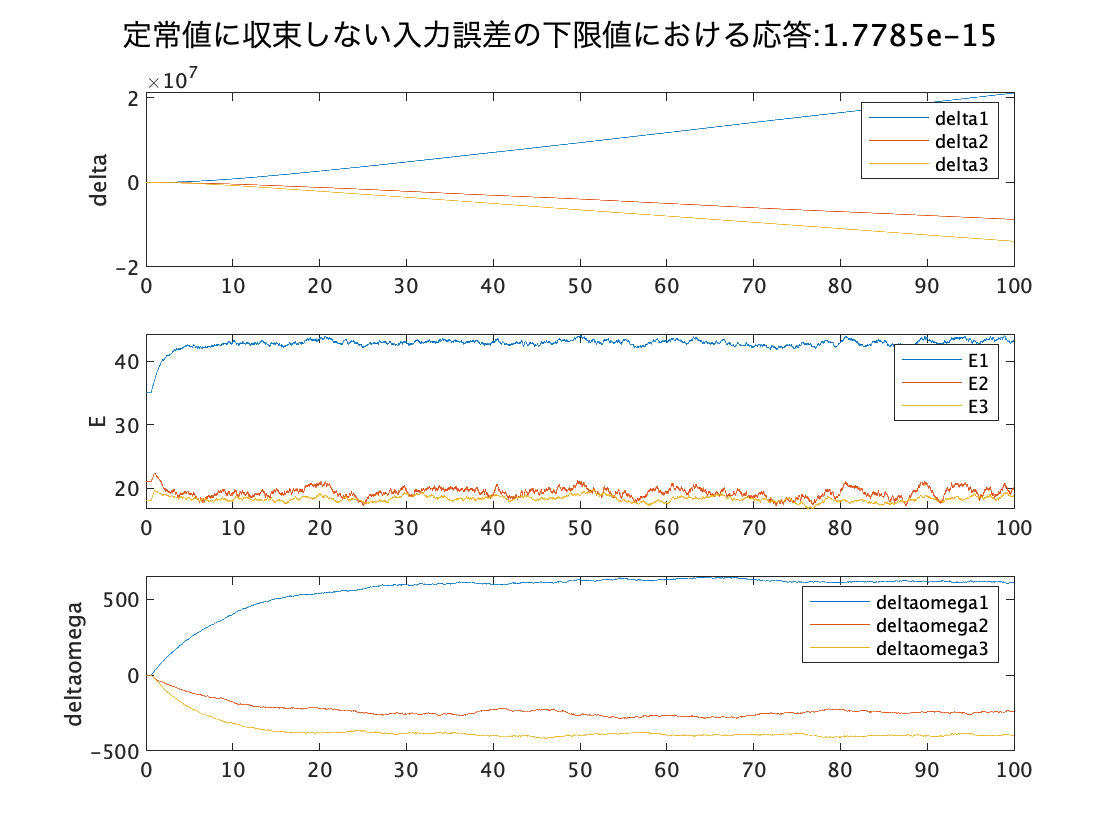

figure;
plot_generator_state(right,tspan,initial_generator_state)
sgtitle(['定常値に収束しない入力誤差の下限値における応答:',num2str(10^right)])

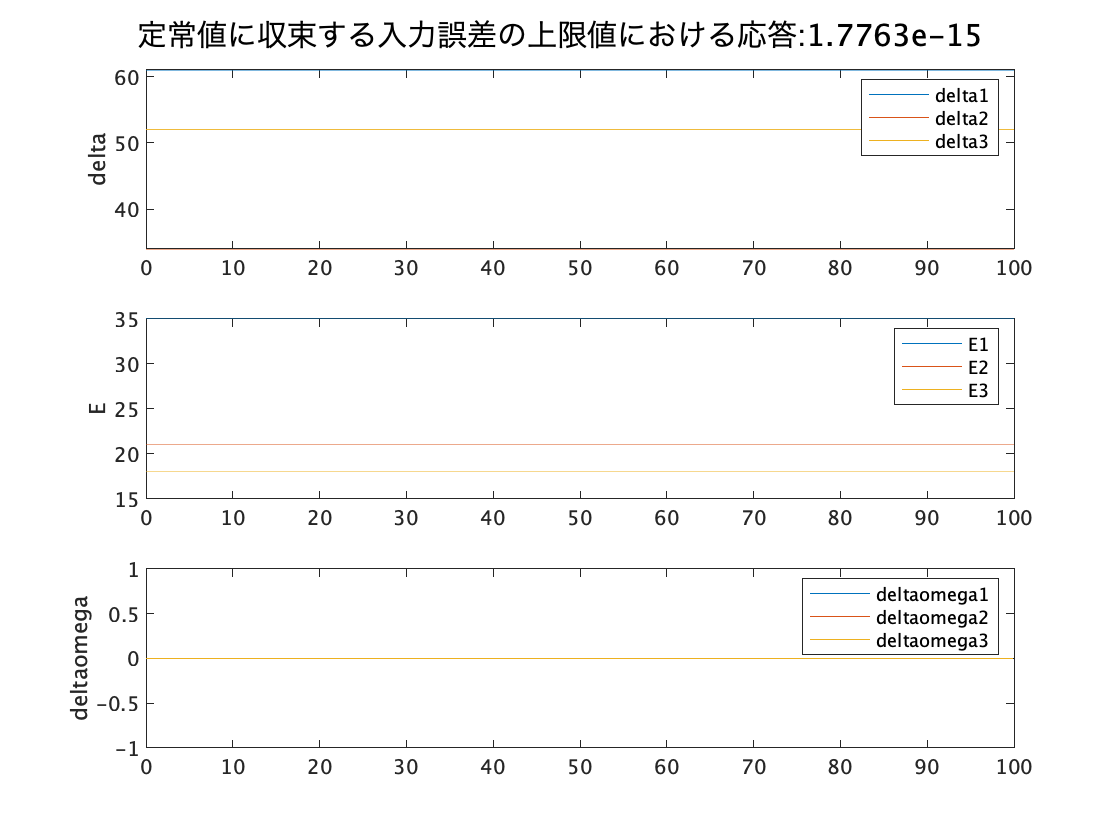

figure;
plot_generator_state(left,tspan,initial_generator_state)
sgtitle(['定常値に収束する入力誤差の上限値における応答:',num2str(10^left)])

clear
for t = 1:5
    figure;
    plot(t,t.^2,'o')
    hold on
end
hold off